# Playing with Puma solutions

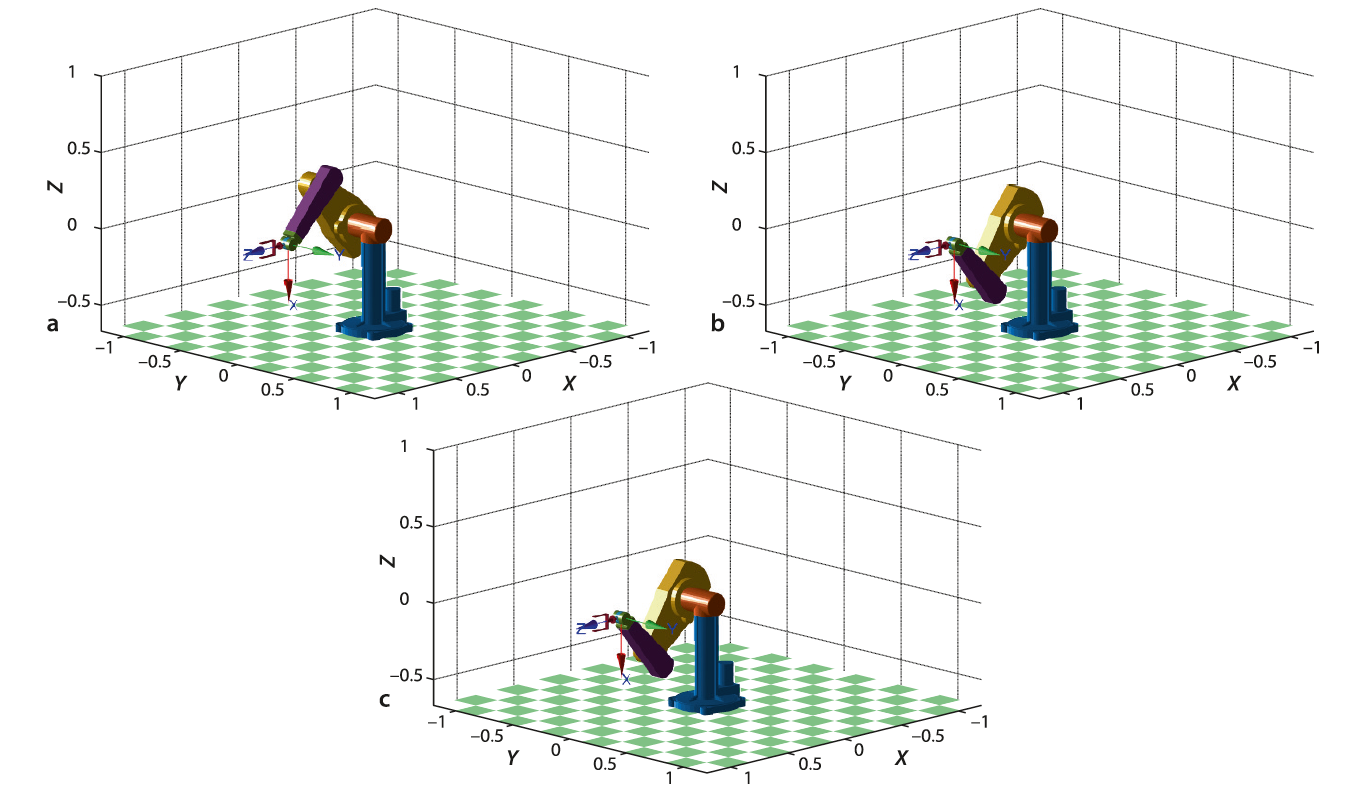

Different configurations of the Puma 560 robot.

a)  Rightup-noflip; 

b)  Right-down-noflip;

c)  Right-down-flip

## Get a pose

clear
mdl_puma560
T=p560.fkine(qn)

## Clone the Puma

p560LUF= SerialLink(p560, 'name', 'p560luf');
p560LUN= SerialLink(p560, 'name', 'p560lun');

## Get different solutions

help seriallink/ikine6s to get familiar with the ikine function.

Q = R.ikine6s(T, CONFIG) as above but specifies the configuration of the arm in

  the form of a string containing one or more of the configuration codes:

  'l'   arm to the left (default)

  'r'   arm to the right

  'u'   elbow up (default)

  'd'   elbow down

  'n'   wrist not flipped (default)

  'f'   wrist flipped (rotated by 180 deg)

qiluf = p560.ikine6s(T, 'luf')
qilufdeg=qiluf*180/pi
qilun = p560.ikine6s(T, 'lun')
qilundeg=qilun*180/pi

## Plotting Puma configuration

subplot(121)
p560LUF.plot(qiluf)
subplot(122)
p560LUN.plot(qilun)

## Play with teach 

Get inside of the concept wrist fliped 

p560LUN.teach(qilun,'eul')